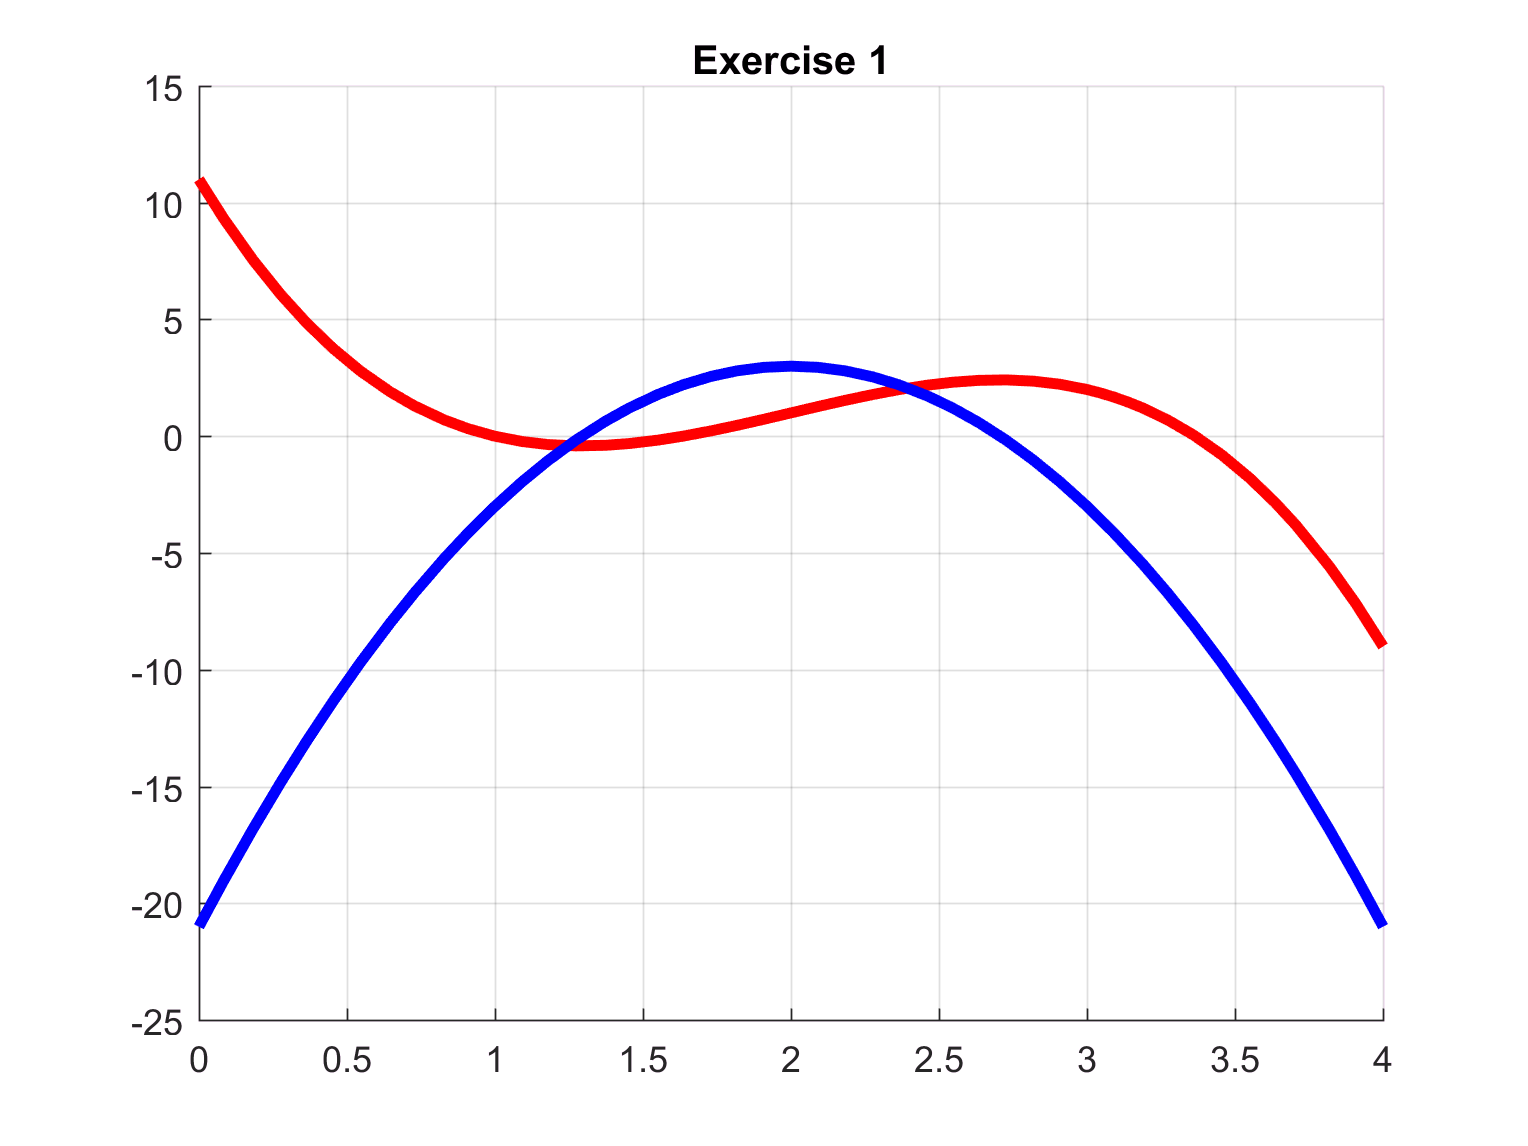

%Exercise 1
clear; clc; figure;

syms t;
f(t)=-2*(t-2)^3+3*(t-2)+1;
v(t)=diff(f(t));

hold on;
fplot(f(t),[0 4],'-r','LineWidth',3);
fplot(v(t),[0 4],'-b','LineWidth',3);
grid on;
title('Exercise 1');

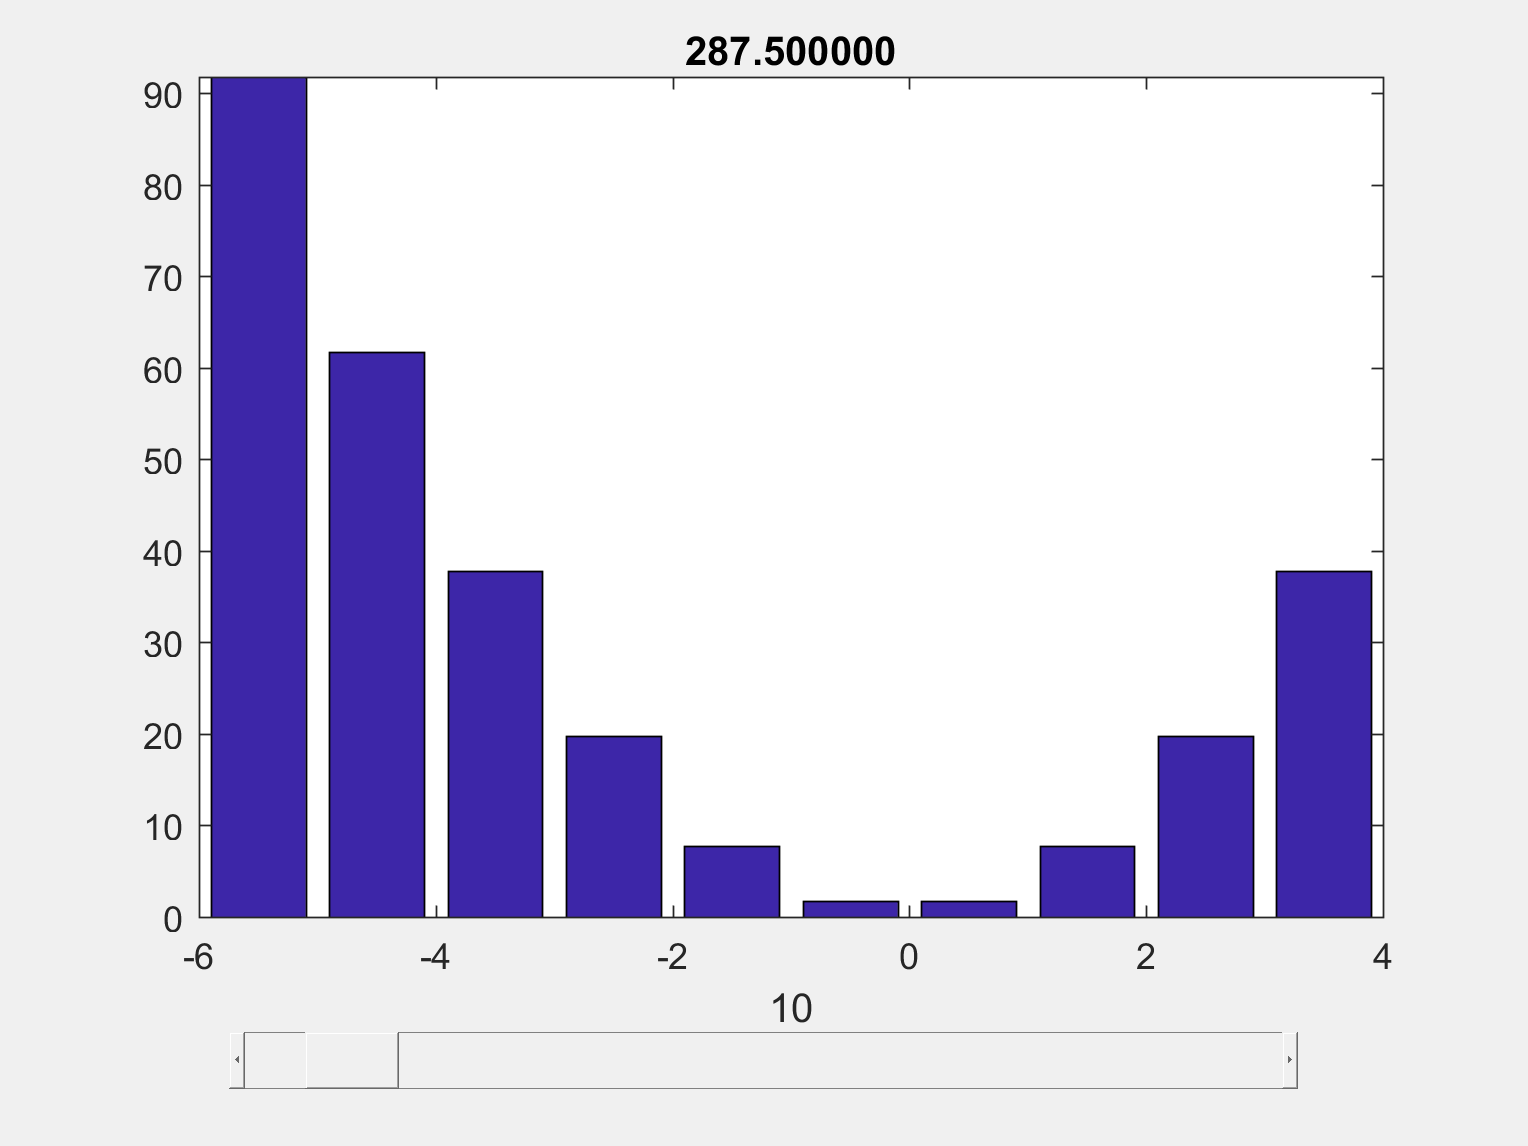

%Exercise 2
clear;clc; figure;

%a)
syms t x;
v(t) = 3*t^2 + 1;
rsums(v(t),[-6 4])

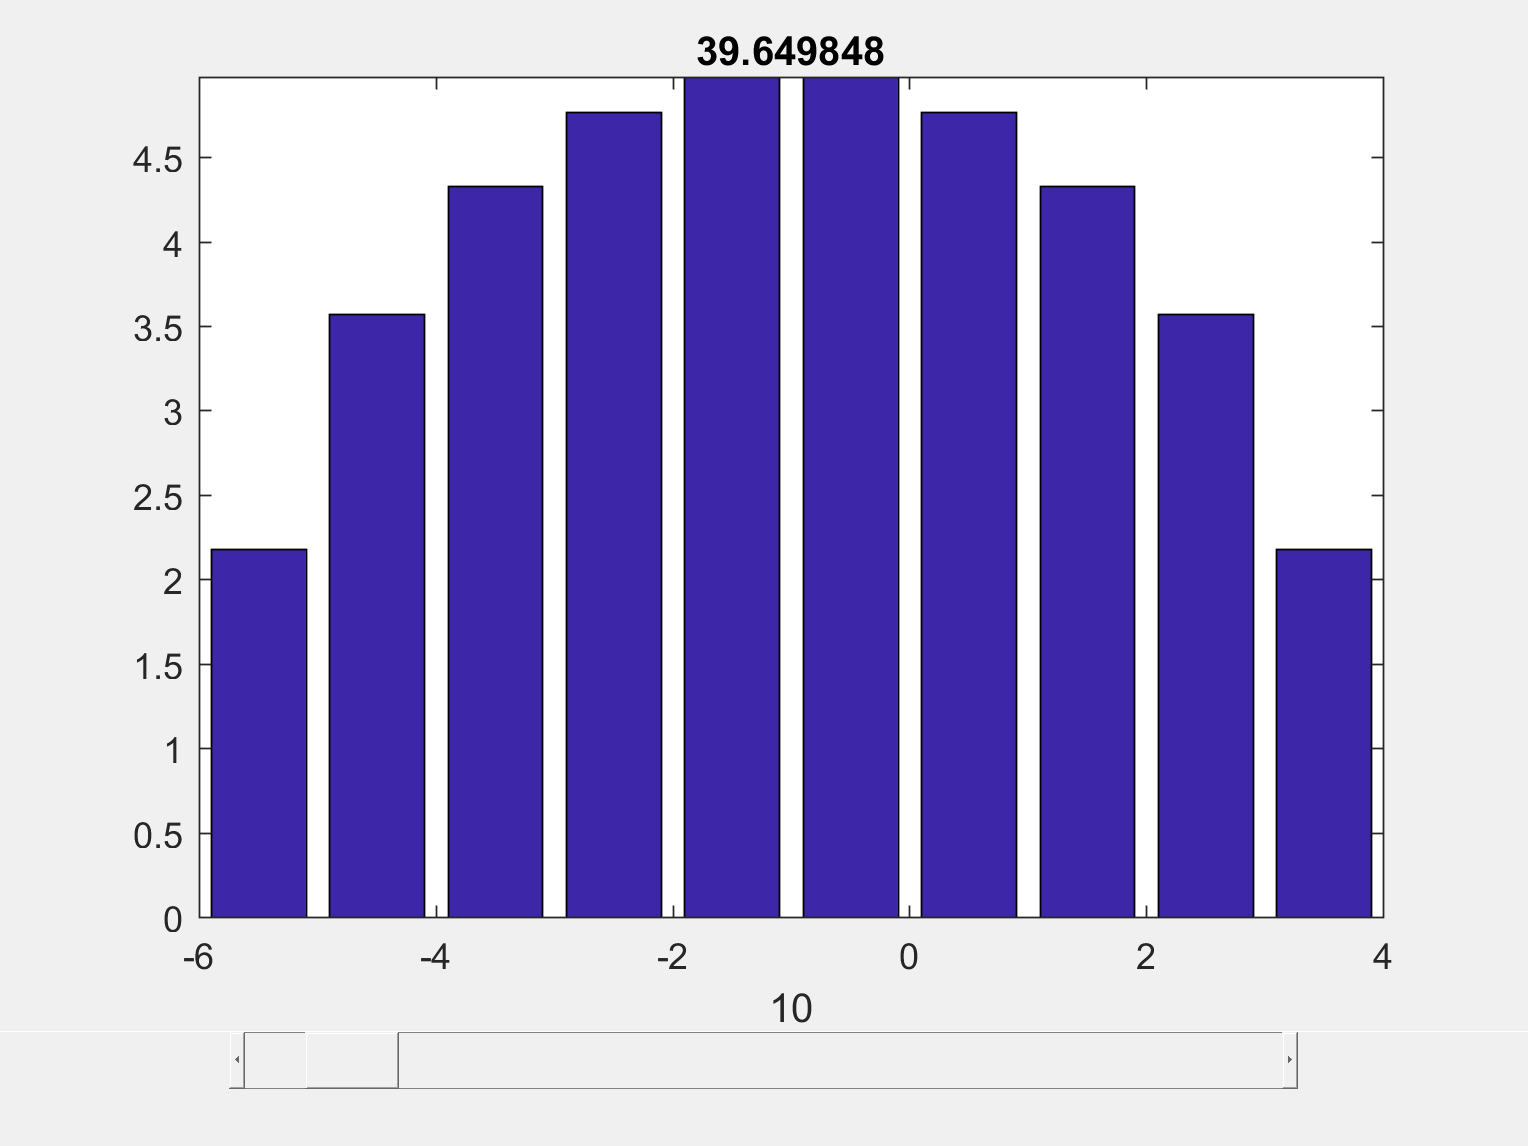


%b)
f(x) = sqrt(24-2*x-x^2);
rsums(f(x),[-6 4])

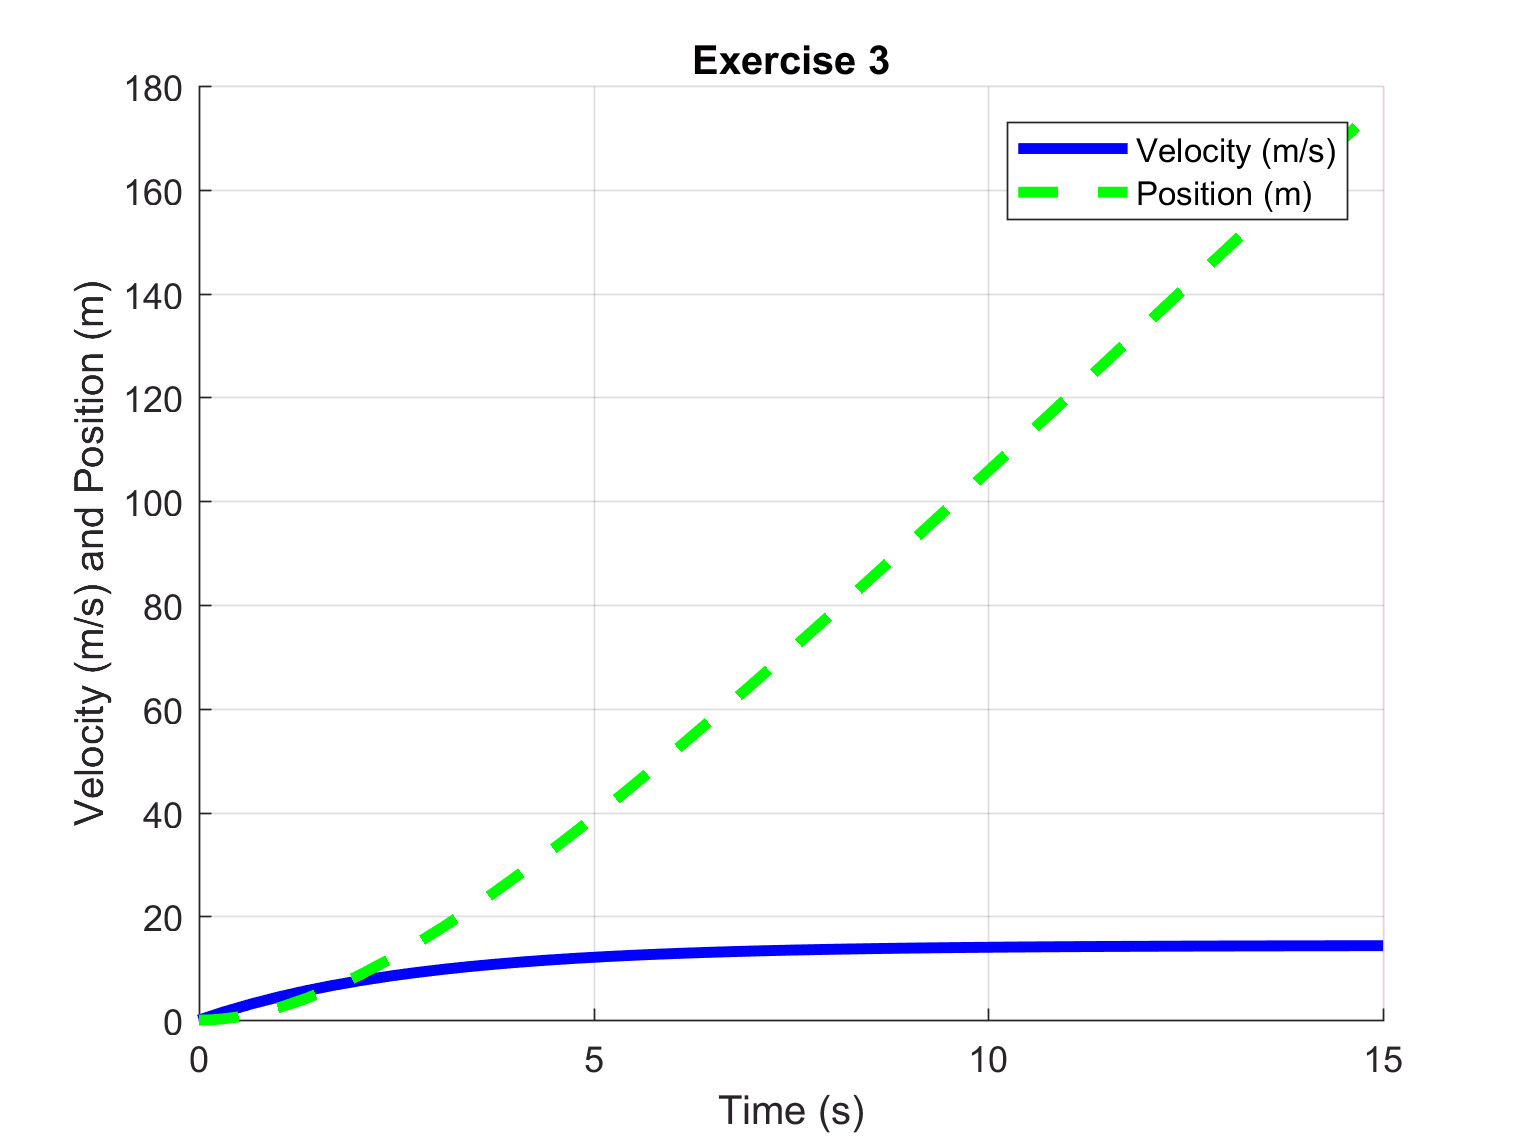

%Exercise 3
clear;clc; figure;

syms t;
A = 14.4; b = 2.72;
v(t) = A*(1-exp(-t/b));
x1(t) = int(v(t));
x(t) = int(v(t)) - x1(0);

hold on;
fplot(v(t), [0 15], '-b', 'LineWidth', 3);
fplot(x(t), [0 15], '--g', 'LineWidth', 3);
grid on;
hold off;
title('Exercise 3');
xlabel('Time (s)');
ylabel('Velocity (m/s) and Position (m)');
legend('Velocity (m/s)', 'Position (m)');


% How long does it take this runner to reach 100 m?
time_at_100m = solve(x(t)==100);
time_at_100m_approx = eval(time_at_100m);
% Answer = 9.584224248475492 seconds

% What was their instantaneous speed at that time in km/h?
speed_at_100m = v(time_at_100m);
speed_at_100m_approx = eval(speed_at_100m);
inst_speed = speed_at_100m_approx * (0.001/(1/3600));
% Answer = 13.975304844870250 km/h